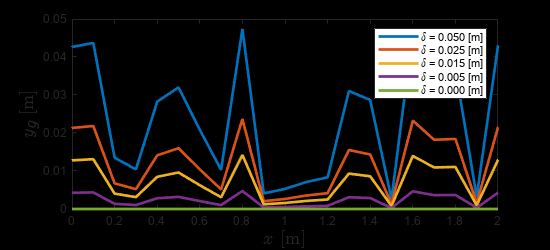

load("terrain data\unevenground_v3_3.mat")
lineW = 2;
figure()
plot(uneven_terrain.x_g, 0.05.*uneven_terrain.y_g_seed, ...
    'LineWidth', lineW, 'DisplayName', '\delta = 0.050 [m]')
hold on
plot(uneven_terrain.x_g, 0.025.*uneven_terrain.y_g_seed, ...
    'LineWidth', lineW, 'DisplayName', '\delta = 0.025 [m]')
plot(uneven_terrain.x_g, 0.015.*uneven_terrain.y_g_seed, ...
    'LineWidth', lineW, 'DisplayName', '\delta = 0.015 [m]')
plot(uneven_terrain.x_g, 0.005.*uneven_terrain.y_g_seed, ...
    'LineWidth', lineW, 'DisplayName', '\delta = 0.005 [m]')
plot(uneven_terrain.x_g, 0.000.*uneven_terrain.y_g_seed, ...
    'LineWidth', lineW, 'DisplayName', '\delta = 0.000 [m]')
xlim([0,2])
ylim([0,0.05])
% title('Uneven Terrain')
label_font_size = 14;
ylabel('$y_g$ [m]', 'Interpreter', "latex",'FontSize',label_font_size)
xlabel('$x$ [m]', 'Interpreter', "latex",'FontSize',label_font_size)
legend

fig_size = 250;
set(gcf,'position',[0,0,fig_size*2.2,fig_size])

f_print = 1;
if f_print == 1
    set(gcf, 'color', 'none');
    set(gca, 'color', 'none');
    print(gcf,'fig_rough_terrain_delta_change.png','-dpng','-r300');
end

f_print = 0; % print flag

figure()

delta = 51; % [m]

terrain_name_start = 1;
terrain_name_end = 10;
indexes = terrain_name_start:terrain_name_end

indexes =      1     2     3     4     5     6     7     8     9    10


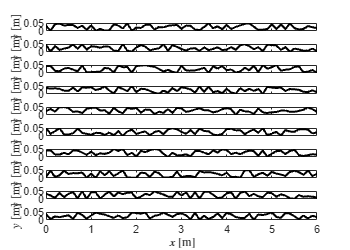


for i = terrain_name_start:terrain_name_end
    terrain_name = "terrain data\unevenground_v3_" + int2str(i) + ".mat";
    load(terrain_name)
    subplot(length(indexes), 1, i)
    current_index = indexes(i);
    plot(uneven_terrain.x_g, 0.05.*uneven_terrain.y_g_seed, "LineWidth", 1.5, "Color", "k")
    
    xlim([0,6])
    ylabel("$y$ [m]", "Interpreter", "latex")
    
    xl = get(gca,'XTickLabel');
    set(gca,'XTickLabel','')
    
    if f_print == 1
        set(gcf, 'color', 'none');
        set(gca, 'color', 'none');
    end
end

set(gca,'XTickLabel',xl)
xlabel('$x$ [m]', "Interpreter", "latex") 

fig_size = 250;
set(gcf,'position',[0,0,fig_size*1.4,fig_size])


if f_print == 1
    print(gcf,'terrain_sample.png','-dpng','-r300');
end